T = 1:400;
N = 10;
tmin = 25;
t0 = 1;

x =     0.0000    0.0001    0.0004    0.0011    0.0025    0.0057    0.0118    0.0231    0.0424    0.0730    0.1180    0.1800    0.2591    0.3531    0.4571    0.5642    0.6667    0.7581    0.8339    0.8923    0.9342    0.9623    0.9797    0.9898    0.9952    0.9979    0.9991    0.9997    0.9999    1.0000


x =     0.0000    0.0001    0.0004    0.0011    0.0025    0.0057    0.0118    0.0231    0.0424    0.0730    0.1180    0.1800    0.2591    0.3531    0.4571    0.5642    0.6667    0.7581    0.8339    0.8923    0.9342    0.9623    0.9797    0.9898    0.9952    0.9979    0.9991    0.9997    0.9999    1.0000


x =     0.0000    0.0001    0.0004    0.0011    0.0025    0.0057    0.0118    0.0231    0.0424    0.0730    0.1180    0.1800    0.2591    0.3531    0.4571    0.5642    0.6667    0.7581    0.8339    0.8923    0.9342    0.9623    0.9797    0.9898    0.9952    0.9979    0.9991    0.9997    0.9999    1.0000


x =     0.0000    0.0001    0.0004    0.0011    0.0025    0.0057    0.0118    0.0231    0.0424    0.0730    0.1180    0.1800    0.2591    0.3531    0.4571    0.5642    0.6667    0.7581    0.8339    0.8923    0.9342    0.9623    0.9797    0.9898    0.9952    0.9979    0.9991    0.9997    0.9999    1.0000


x =     0.0000    0.0001    0.0004    0.0011    0.0025    0.0057    0.0118    0.0231    0.0424    0.0730    0.1180    0.1800    0.2591    0.3531    0.4571    0.5642    0.6667    0.7581    0.8339    0.8923    0.9342    0.9623    0.9797    0.9898    0.9952    0.9979    0.9991    0.9997    0.9999    1.0000


x =     0.0000    0.0001    0.0004    0.0011    0.0025    0.0057    0.0118    0.0231    0.0424    0.0730    0.1180    0.1800    0.2591    0.3531    0.4571    0.5642    0.6667    0.7581    0.8339    0.8923    0.9342    0.9623    0.9797    0.9898    0.9952    0.9979    0.9991    0.9997    0.9999    1.0000


x =     0.0000    0.0001    0.0004    0.0011    0.0025    0.0057    0.0118    0.0231    0.0424    0.0730    0.1180    0.1800    0.2591    0.3531    0.4571    0.5642    0.6667    0.7581    0.8339    0.8923    0.9342    0.9623    0.9797    0.9898    0.9952    0.9979    0.9991    0.9997    0.9999    1.0000


x =     0.0000    0.0001    0.0004    0.0011    0.0025    0.0057    0.0118    0.0231    0.0424    0.0730    0.1180    0.1800    0.2591    0.3531    0.4571    0.5642    0.6667    0.7581    0.8339    0.8923    0.9342    0.9623    0.9797    0.9898    0.9952    0.9979    0.9991    0.9997    0.9999    1.0000


x =     0.0000    0.0001    0.0004    0.0011    0.0025    0.0057    0.0118    0.0231    0.0424    0.0730    0.1180    0.1800    0.2591    0.3531    0.4571    0.5642    0.6667    0.7581    0.8339    0.8923    0.9342    0.9623    0.9797    0.9898    0.9952    0.9979    0.9991    0.9997    0.9999    1.0000


u = binrand(T, N, tmin, t0, 'normal');

% Define the transfer functions
numerator = [1, 0];
denominator = [10, -10];
ts = 0.01;
C = tf(numerator, denominator, ts);

num = [0.1812];
den = [1, -0.8187];
G = tf(num, den, ts);

delay=tf(1,[1 0 0 0 0 0 0 0 0 0 0], ts);

variance1 = 0.1; % also for 0.01 and 0.001
variance2 = 0.01;
variance3 = 0.001;
noise1 = sqrt(variance1) * randn(size(u));
noise2 = sqrt(variance2) * randn(size(u));
noise3 = sqrt(variance3) * randn(size(u));

Ts = 0.01;                % Sample time of the models
N = length(u); 
timeVector = 0:Ts:(N-1)*Ts;

output1 = lsim((G*C)/(1+(G*C)), u.', timeVector.') + lsim(1/(1+C*G), noise1.', timeVector.');
output2 = lsim((G*C)/(1+(G*C)), u.', timeVector.') + lsim(1/(1+C*G), noise2.', timeVector.');
output3 = lsim((G*C)/(1+(G*C)), u.', timeVector.') + lsim(1/(1+C*G), noise3.', timeVector.');

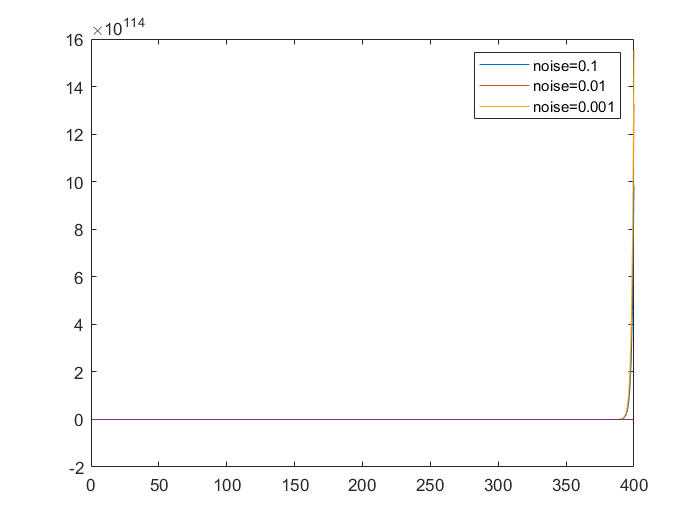

figure;
plot(output1)
hold on
plot(output2)
plot(output3)
plot(u)
legend('noise=0.1','noise=0.01', 'noise=0.001');
hold off

pairs1 = table(u.', output1, 'VariableNames', {'Input', 'Output'});
pairs2 = table(u.', output2, 'VariableNames', {'Input', 'Output'});
pairs3 = table(u.', output3, 'VariableNames', {'Input', 'Output'});

% Define a range of values for na, nb, and nk
% Parameters
na_values = [1, 2, 3 ,4 , 5];  % List of 'na' values to test
nc_values = [1, 2, 3 ,4, 5,6,7];  % List of 'na' values to test
nb_values = [1, 2, 3 ,4 , 5];  % List of 'nb' values to test
nf_values = [1, 2, 3 ,4,5];  % List of 'na' values to test
nd_values = [1, 2, 3 ,4, 5];  % List of 'na' values to test
nk_values = [0];  % List of 'nk' values to test
best_na = 0;            % Variable to store the best 'na' value
best_nb = 0;            % Variable to store the best 'nb' value
best_nk = 0;            % Variable to store the best 'nk' value
best_nc = 0;            % Variable to store the best 'nk' value
best_nf = 0;            % Variable to store the best 'nk' value
best_nd = 0;            % Variable to store the best 'nk' value
best_val_error = Inf;   % Variable to store the best validation error
best_model = [];        % Variable to store the best model

% ARX with 0.1 noise
best_y_pred = [];  

for na = na_values
    for nb = nb_values
        for nk = nk_values
            % ARX Model Identification
            sys = arx(iddata(output1, u.', 0.01), [na, nb, nk]);  % Set Ts to 0.01
            sys.Ts = 0.01;  
            y_val_pred = compare(sys, iddata(output1, u.', 0.01)); 
            val_error = mean((y_val_pred.OutputData - output1).^2);
            if val_error < best_val_error
                best_val_error = val_error;
                best_na = na;
                best_nb = nb;
                best_nk = nk;
                best_model = sys;  % Store the best model
                best_y_pred = y_val_pred.OutputData;  
            end
        end
    end
end


disp(['Best na value: ', num2str(best_na)]);

Best na value: 1


disp(['Best nb value: ', num2str(best_nb)]);

Best nb value: 1


disp(['Best nk value: ', num2str(best_nk)]);

Best nk value: 1


disp(['Best validation error (MSE): ', num2str(best_val_error)]);

Best validation error (MSE): 1.783329090304451e+204



% Display the best model
disp('Best model:');

Best model:


disp(best_model);

  idpoly with properties:

                 A: [1 -1.9631]
                 B: [0 0]
                 C: 1
                 D: 1
                 F: 1
    IntegrateNoise: 0
          Variable: 'z^-1'
           IODelay: 0
         Structure: [1×1 pmodel.polynomial]
     NoiseVariance: 3.0456e+204
            Report: [1×1 idresults.arx]
        InputDelay: 0
       OutputDelay: 0
                Ts: 0.0100
          TimeUnit: 'seconds'
         InputName: {'u1'}
         InputUnit: {''}
        InputGroup: [1×1 struct]
        OutputName: {'y1'}
        OutputUnit: {''}
       OutputGroup: [1×1 struct]
             Notes: [0×1 string]
          UserData: []
              Name: ''
      SamplingGrid: [1×1 struct]



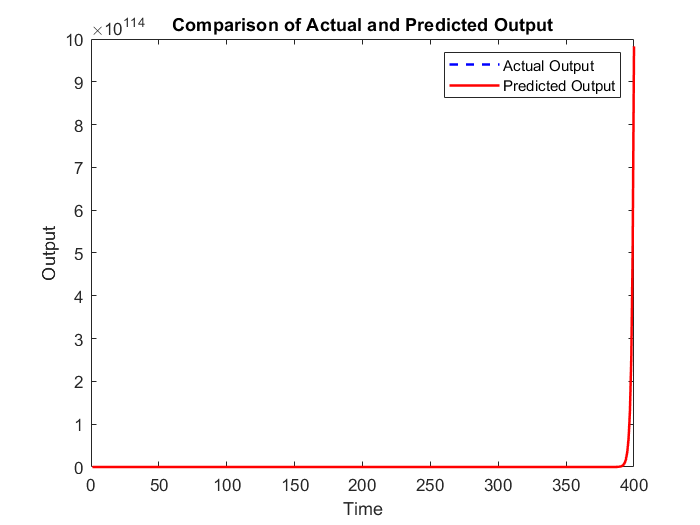

% Plot the actual output and predicted output
figure;
t = 1:length(output1);
plot(t, output1, 'b--', 'LineWidth', 1.5);
hold on;
plot(t, best_y_pred, 'r', 'LineWidth', 1.5);
hold off;
xlabel('Time');
ylabel('Output');
legend('Actual Output', 'Predicted Output');
title('Comparison of Actual and Predicted Output');

best_model

best_model =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
  A(z) = 1 - 1.963 z^-1                            
                                                   
  B(z) = 0                                         
                                                   
Sample time: 0.01 seconds
  
Parameterization:
   Polynomial orders:   na=1   nb=1   nk=1
   Number of free coefficients: 2
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                        
Estimated using ARX on time domain data.       
Fit to estimation data: 100% (prediction focus)
FPE: 3.068e+204, MSE: 3.023e+204               


% Extract zeros and poles from the estimated ARX model
zeros_est = zero(best_model);
poles_est = pole(best_model);

% Display the zero locations and poles
disp('Estimated Model:');

Estimated Model:


disp('Zeros:');

Zeros:


disp(zeros_est);
disp('Poles:');

Poles:


disp(poles_est);

    1.9631



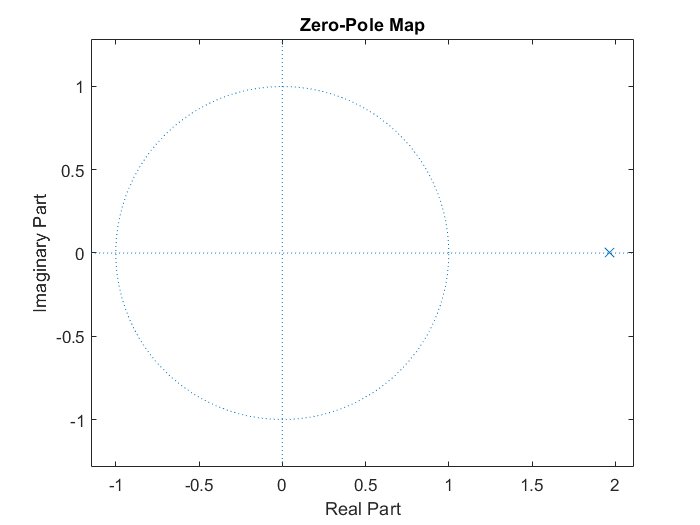


% Plot the zero-pole map
figure;
zplane(zeros_est, poles_est);
title('Zero-Pole Map');

e = u.' - best_y_pred;
corr_eu = corrcoef(e, u.');
corr_eu = corr_eu(1, 2); % Extract the correlation coefficient from the matrix

% Calculate the correlation between e and y
corr_ey = corrcoef(e, best_y_pred);
corr_ey = corr_ey(1, 2); % Extract the correlation coefficient from the matrix

% Display the correlation coefficients
disp('Correlation between e and u:');

Correlation between e and u:


disp(corr_eu);

    0.0230



disp('Correlation between e and y:');

Correlation between e and y:


disp(corr_ey);

    -1



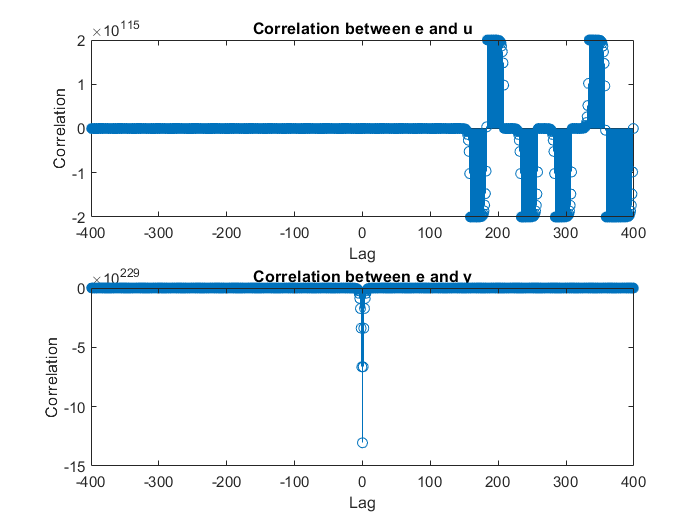


corr_eu = xcorr(e, u.');

% Calculate the correlation between e and y
corr_ey = xcorr(e, best_y_pred);

% Plot the correlation results
lags = -(length(e)-1):(length(e)-1);
figure;
subplot(2, 1, 1);
stem(lags, corr_eu);
title('Correlation between e and u');
xlabel('Lag');
ylabel('Correlation');
subplot(2, 1, 2);
stem(lags, corr_ey);
title('Correlation between e and y');
xlabel('Lag');
ylabel('Correlation');

% ARX with 0.01 noise
best_y_pred = [];  
best_na = 0;            % Variable to store the best 'na' value
best_nb = 0;            % Variable to store the best 'nb' value
best_nk = 0;            % Variable to store the best 'nk' value
best_nc = 0;            % Variable to store the best 'nk' value
best_nf = 0;            % Variable to store the best 'nk' value
best_nd = 0;            % Variable to store the best 'nk' value
best_val_error = Inf;   % Variable to store the best validation error
best_model = [];        % Variable to store the best model
for na = na_values
    for nb = nb_values
        for nk = nk_values
            % ARX Model Identification
            sys = arx(iddata(output2, u.', 0.01), [na, nb, nk]);  % Set Ts to 0.01
            sys.Ts = 0.01;  
            y_val_pred = compare(sys, iddata(output2, u.', 0.01)); 
            val_error = mean((y_val_pred.OutputData - output2).^2);
            if val_error < best_val_error
                best_val_error = val_error;
                best_na = na;
                best_nb = nb;
                best_nk = nk;
                best_model = sys;  % Store the best model
                best_y_pred = y_val_pred.OutputData;  
            end
        end
    end
end


disp(['Best na value: ', num2str(best_na)]);

Best na value: 1


disp(['Best nb value: ', num2str(best_nb)]);

Best nb value: 1


disp(['Best nk value: ', num2str(best_nk)]);

Best nk value: 1


disp(['Best validation error (MSE): ', num2str(best_val_error)]);

Best validation error (MSE): 1.78318073862089e+204



% Display the best model
disp('Best model:');

Best model:


disp(best_model);

  idpoly with properties:

                 A: [1 -1.9631]
                 B: [0 0]
                 C: 1
                 D: 1
                 F: 1
    IntegrateNoise: 0
          Variable: 'z^-1'
           IODelay: 0
         Structure: [1×1 pmodel.polynomial]
     NoiseVariance: 3.0456e+204
            Report: [1×1 idresults.arx]
        InputDelay: 0
       OutputDelay: 0
                Ts: 0.0100
          TimeUnit: 'seconds'
         InputName: {'u1'}
         InputUnit: {''}
        InputGroup: [1×1 struct]
        OutputName: {'y1'}
        OutputUnit: {''}
       OutputGroup: [1×1 struct]
             Notes: [0×1 string]
          UserData: []
              Name: ''
      SamplingGrid: [1×1 struct]



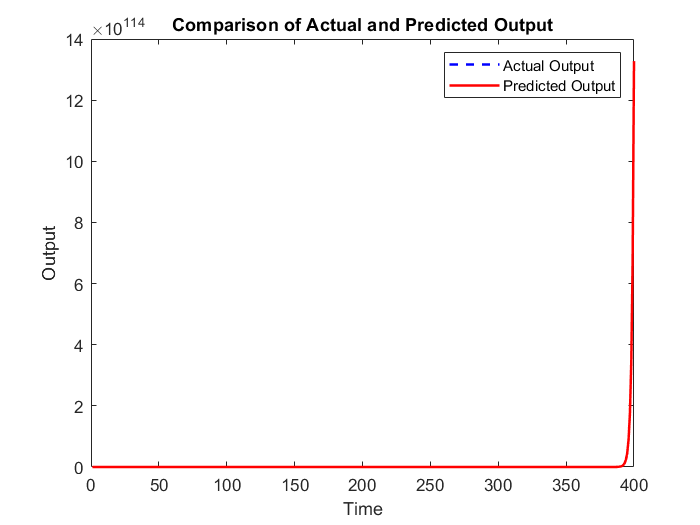

% Plot the actual output and predicted output
figure;
t = 1:length(output2);
plot(t, output2, 'b--', 'LineWidth', 1.5);
hold on;
plot(t, best_y_pred, 'r', 'LineWidth', 1.5);
hold off;
xlabel('Time');
ylabel('Output');
legend('Actual Output', 'Predicted Output');
title('Comparison of Actual and Predicted Output');

best_model

best_model =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
  A(z) = 1 - 1.963 z^-1                            
                                                   
  B(z) = 0                                         
                                                   
Sample time: 0.01 seconds
  
Parameterization:
   Polynomial orders:   na=1   nb=1   nk=1
   Number of free coefficients: 2
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                        
Estimated using ARX on time domain data.       
Fit to estimation data: 100% (prediction focus)
FPE: 3.068e+204, MSE: 3.023e+204               


% Extract zeros and poles from the estimated ARX model
zeros_est = zero(best_model);
poles_est = pole(best_model);

% Display the zero locations and poles
disp('Estimated Model:');

Estimated Model:


disp('Zeros:');

Zeros:


disp(zeros_est);
disp('Poles:');

Poles:


disp(poles_est);

    1.9631




% Plot the zero-pole map
figure;
zplane(zeros_est, poles_est);
title('Zero-Pole Map');

e = u.' - best_y_pred;
corr_eu = corrcoef(e, u.');
corr_eu = corr_eu(1, 2); % Extract the correlation coefficient from the matrix

% Calculate the correlation between e and y
corr_ey = corrcoef(e, best_y_pred);
corr_ey = corr_ey(1, 2); % Extract the correlation coefficient from the matrix

% Display the correlation coefficients
disp('Correlation between e and u:');

Correlation between e and u:


disp(corr_eu);

    0.0230



disp('Correlation between e and y:');

Correlation between e and y:


disp(corr_ey);

    -1



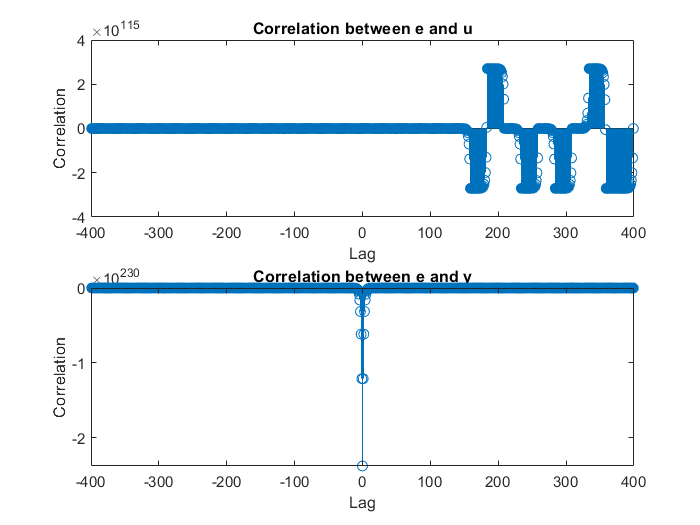


corr_eu = xcorr(e, u.');

% Calculate the correlation between e and y
corr_ey = xcorr(e, best_y_pred);

% Plot the correlation results
lags = -(length(e)-1):(length(e)-1);
figure;
subplot(2, 1, 1);
stem(lags, corr_eu);
title('Correlation between e and u');
xlabel('Lag');
ylabel('Correlation');
subplot(2, 1, 2);
stem(lags, corr_ey);
title('Correlation between e and y');
xlabel('Lag');
ylabel('Correlation');

% ARX with 0.01 noise
best_y_pred = [];  
best_na = 0;            % Variable to store the best 'na' value
best_nb = 0;            % Variable to store the best 'nb' value
best_nk = 0;            % Variable to store the best 'nk' value
best_nc = 0;            % Variable to store the best 'nk' value
best_nf = 0;            % Variable to store the best 'nk' value
best_nd = 0;            % Variable to store the best 'nk' value
best_val_error = Inf;   % Variable to store the best validation error
best_model = [];        % Variable to store the best model
for na = na_values
    for nb = nb_values
        for nk = nk_values
            % ARX Model Identification
            sys = arx(iddata(output3, u.', 0.01), [na, nb, nk]);  % Set Ts to 0.01
            sys.Ts = 0.01;  
            y_val_pred = compare(sys, iddata(output3, u.', 0.01)); 
            val_error = mean((y_val_pred.OutputData - output3).^2);
            if val_error < best_val_error
                best_val_error = val_error;
                best_na = na;
                best_nb = nb;
                best_nk = nk;
                best_model = sys;  % Store the best model
                best_y_pred = y_val_pred.OutputData;  
            end
        end
    end
end


disp(['Best na value: ', num2str(best_na)]);

Best na value: 1


disp(['Best nb value: ', num2str(best_nb)]);

Best nb value: 3


disp(['Best nk value: ', num2str(best_nk)]);

Best nk value: 0


disp(['Best validation error (MSE): ', num2str(best_val_error)]);

Best validation error (MSE): 1.783195749079707e+204



% Display the best model
disp('Best model:');

Best model:


disp(best_model);

  idpoly with properties:

                 A: [1 -1.9631]
                 B: [0 0 0]
                 C: 1
                 D: 1
                 F: 1
    IntegrateNoise: 0
          Variable: 'z^-1'
           IODelay: 0
         Structure: [1×1 pmodel.polynomial]
     NoiseVariance: 3.0612e+204
            Report: [1×1 idresults.arx]
        InputDelay: 0
       OutputDelay: 0
                Ts: 0.0100
          TimeUnit: 'seconds'
         InputName: {'u1'}
         InputUnit: {''}
        InputGroup: [1×1 struct]
        OutputName: {'y1'}
        OutputUnit: {''}
       OutputGroup: [1×1 struct]
             Notes: [0×1 string]
          UserData: []
              Name: ''
      SamplingGrid: [1×1 struct]



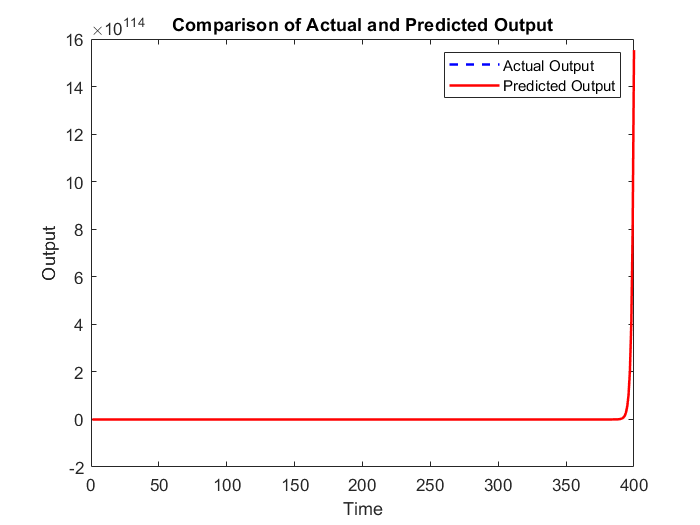

% Plot the actual output and predicted output
figure;
t = 1:length(output3);
plot(t, output3, 'b--', 'LineWidth', 1.5);
hold on;
plot(t, best_y_pred, 'r', 'LineWidth', 1.5);
hold off;
xlabel('Time');
ylabel('Output');
legend('Actual Output', 'Predicted Output');
title('Comparison of Actual and Predicted Output');

best_model

best_model =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
  A(z) = 1 - 1.963 z^-1                            
                                                   
  B(z) = 0                                         
                                                   
Sample time: 0.01 seconds
  
Parameterization:
   Polynomial orders:   na=1   nb=3   nk=0
   Number of free coefficients: 4
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                        
Estimated using ARX on time domain data.       
Fit to estimation data: 100% (prediction focus)
FPE: 3.099e+204, MSE: 3.023e+204               


% Extract zeros and poles from the estimated ARX model
zeros_est = zero(best_model);
poles_est = pole(best_model);

% Display the zero locations and poles
disp('Estimated Model:');

Estimated Model:


disp('Zeros:');

Zeros:


disp(zeros_est);
disp('Poles:');

Poles:


disp(poles_est);

    1.9631




% Plot the zero-pole map
figure;
zplane(zeros_est, poles_est);
title('Zero-Pole Map');

e = u.' - best_y_pred;
corr_eu = corrcoef(e, u.');
corr_eu = corr_eu(1, 2); % Extract the correlation coefficient from the matrix

% Calculate the correlation between e and y
corr_ey = corrcoef(e, best_y_pred);
corr_ey = corr_ey(1, 2); % Extract the correlation coefficient from the matrix

% Display the correlation coefficients
disp('Correlation between e and u:');

Correlation between e and u:


disp(corr_eu);

    0.0230



disp('Correlation between e and y:');

Correlation between e and y:


disp(corr_ey);

    -1



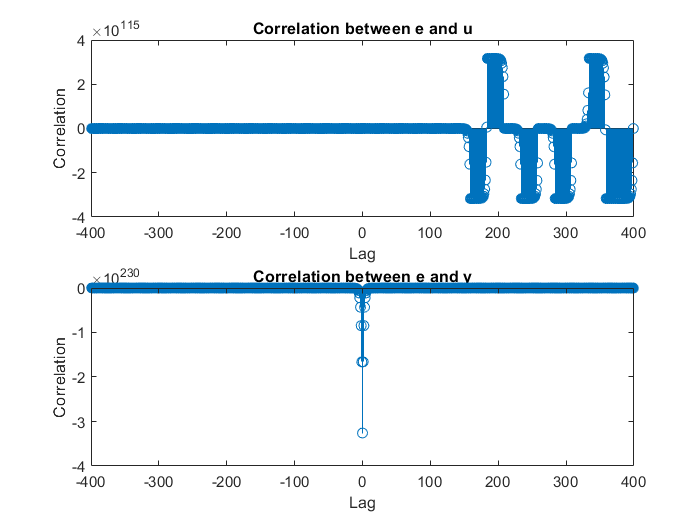


corr_eu = xcorr(e, u.');

% Calculate the correlation between e and y
corr_ey = xcorr(e, best_y_pred);

% Plot the correlation results
lags = -(length(e)-1):(length(e)-1);
figure;
subplot(2, 1, 1);
stem(lags, corr_eu);
title('Correlation between e and u');
xlabel('Lag');
ylabel('Correlation');
subplot(2, 1, 2);
stem(lags, corr_ey);
title('Correlation between e and y');
xlabel('Lag');
ylabel('Correlation');

% ARX with 0.01 noise
best_y_pred = [];  
best_na = 0;            % Variable to store the best 'na' value
best_nb = 0;            % Variable to store the best 'nb' value
best_nk = 0;            % Variable to store the best 'nk' value
best_nc = 0;            % Variable to store the best 'nk' value
best_nf = 0;            % Variable to store the best 'nk' value
best_nd = 0;            % Variable to store the best 'nk' value
best_val_error = Inf;   % Variable to store the best validation error
best_model = [];        % Variable to store the best model
    for nb = nb_values
        for nk = nk_values
            % ARX Model Identification
            sys = arx(iddata(output3, u.', 0.01), [3, nb, nk]);  % Set Ts to 0.01
            sys.Ts = 0.01;  
            y_val_pred = compare(sys, iddata(output3, u.', 0.01)); 
            val_error = mean((y_val_pred.OutputData - output3).^2);
            if val_error < best_val_error
                best_val_error = val_error;
                best_nb = nb;
                best_nk = nk;
                best_model = sys;  % Store the best model
                best_y_pred = y_val_pred.OutputData;  
            end
        end
    end


disp(['Best nb value: ', num2str(best_nb)]);

Best nb value: 5


disp(['Best nk value: ', num2str(best_nk)]);

Best nk value: 1


disp(['Best validation error (MSE): ', num2str(best_val_error)]);

Best validation error (MSE): 1.87966931673666e+206



% Display the best model
disp('Best model:');

Best model:


disp(best_model);

  idpoly with properties:

                 A: [1 -2.9725 0 3.8900]
                 B: [0 0 0 0 0 0]
                 C: 1
                 D: 1
                 F: 1
    IntegrateNoise: 0
          Variable: 'z^-1'
           IODelay: 0
         Structure: [1×1 pmodel.polynomial]
     NoiseVariance: 1.7093e+196
            Report: [1×1 idresults.arx]
        InputDelay: 0
       OutputDelay: 0
                Ts: 0.0100
          TimeUnit: 'seconds'
         InputName: {'u1'}
         InputUnit: {''}
        InputGroup: [1×1 struct]
        OutputName: {'y1'}
        OutputUnit: {''}
       OutputGroup: [1×1 struct]
             Notes: [0×1 string]
          UserData: []
              Name: ''
      SamplingGrid: [1×1 struct]



% Plot the actual output and predicted output
figure;
t = 1:length(output3);
plot(t, output3, 'b--', 'LineWidth', 1.5);
hold on;
plot(t, best_y_pred, 'r', 'LineWidth', 1.5);
hold off;
xlabel('Time');
ylabel('Output');
legend('Actual Output', 'Predicted Output');
title('Comparison of Actual and Predicted Output');

best_model

best_model =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
  A(z) = 1 - 2.973 z^-1 + 3.89 z^-3                
                                                   
  B(z) = 0                                         
                                                   
Sample time: 0.01 seconds
  
Parameterization:
   Polynomial orders:   na=3   nb=5   nk=1
   Number of free coefficients: 8
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                        
Estimated using ARX on time domain data.       
Fit to estimation data: 100% (prediction focus)
FPE: 1.756e+196, MSE: 1.662e+196               


% Extract zeros and poles from the estimated ARX model
zeros_est = zero(best_model);
poles_est = pole(best_model);

% Display the zero locations and poles
disp('Estimated Model:');

Estimated Model:


disp('Zeros:');

Zeros:


disp(zeros_est);
disp('Poles:');

Poles:


disp(poles_est);

    2.0002
    1.9631
   -0.9907



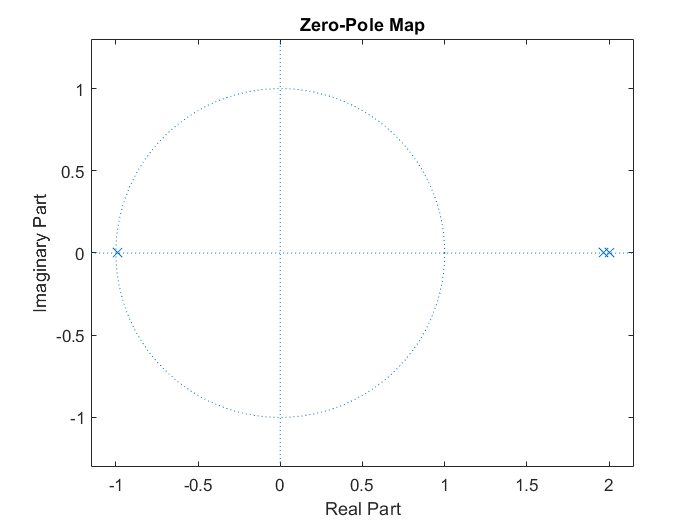


% Plot the zero-pole map
figure;
zplane(zeros_est, poles_est);
title('Zero-Pole Map');